## Model Verification

Static Equilibrium - Mass displacement should be 0 for no velocity, lateral acceleration and road roughness inputs.

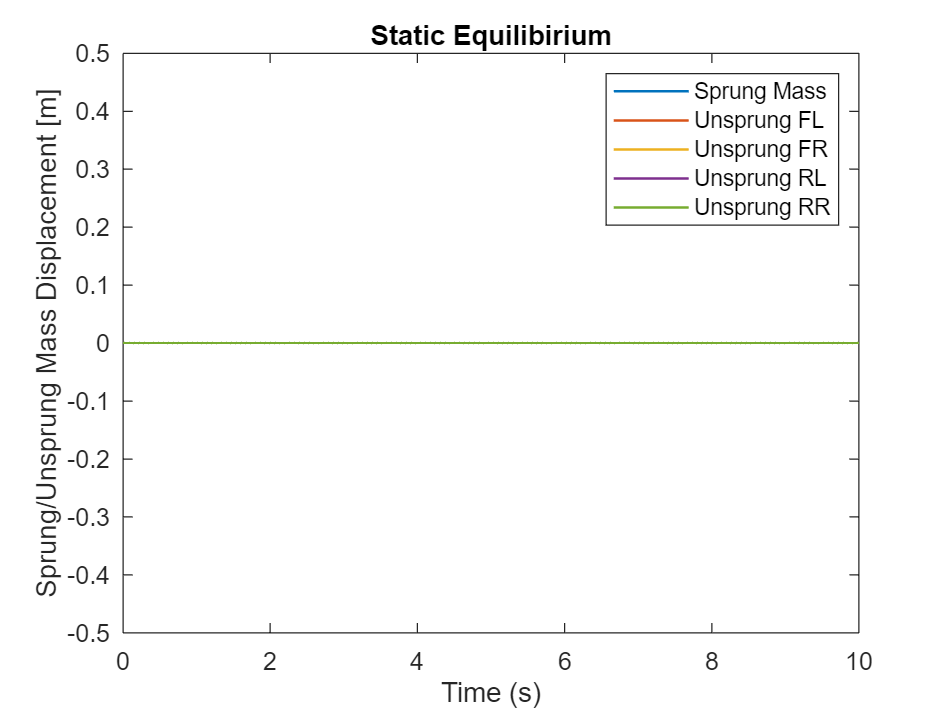

load("Static_Equilibrium.mat")

plot(Static_Equilibrium.zs.time,Static_Equilibrium.zs.data, "LineWidth",1)
hold on
plot(Static_Equilibrium.zusfl.time, Static_Equilibrium.zusfl.data, "LineWidth",1)
plot(Static_Equilibrium.zusfr.time, Static_Equilibrium.zusfr.data, "LineWidth",1)
plot(Static_Equilibrium.zusrl.time, Static_Equilibrium.zusrl.data, "LineWidth",1)
plot(Static_Equilibrium.zusrr.time, Static_Equilibrium.zusrr.data, "LineWidth",1)
ylim([-0.5 0.5])
xlabel('Time (s)')
ylabel('Sprung/Unsprung Mass Displacement [m]')
title('Static Equilibirium')
legend(['Sprung Mass'; 'Unsprung FL'; 'Unsprung FR'; 'Unsprung RL'; 'Unsprung RR'])
hold off

Aero Forces - Ramp velocity input form 0 to 300kmph in 20s.

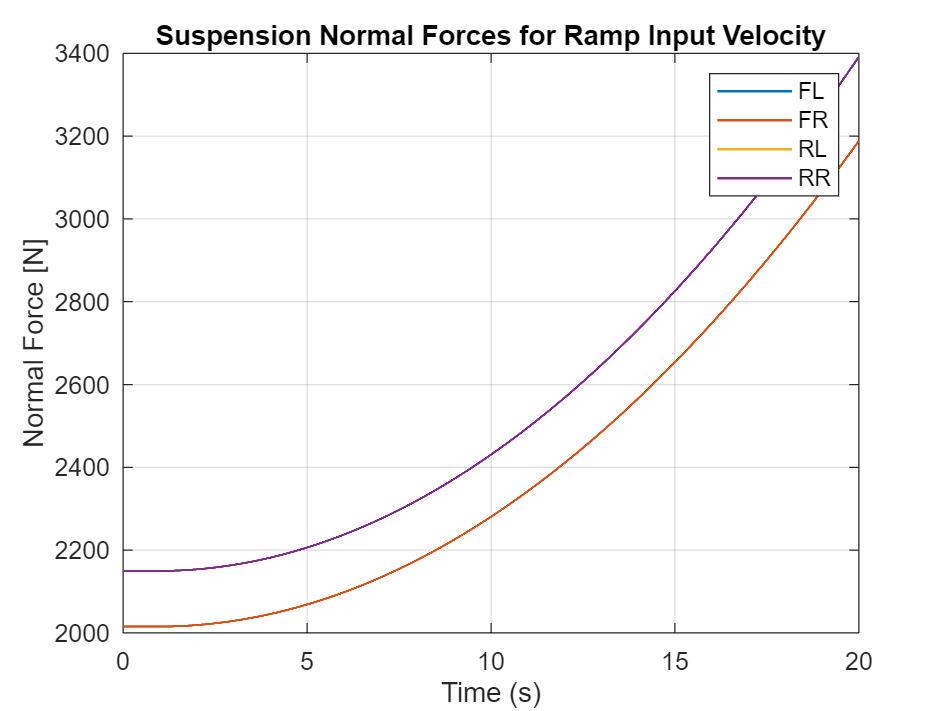

load("Aero_Forces.mat")

plot(Aero_Forces.Ftfl.time, Aero_Forces.Ftfl.data, "LineWidth",1)
hold on
plot(Aero_Forces.Ftfr.time, Aero_Forces.Ftfr.data, "LineWidth",1)
plot(Aero_Forces.Ftrl.time, Aero_Forces.Ftrl.data, "LineWidth",1)
plot(Aero_Forces.Ftrr.time, Aero_Forces.Ftrr.data, "LineWidth",1)
xlabel('Time (s)')
ylabel('Normal Force [N]')
title('Suspension Normal Forces for Ramp Input Velocity')
legend(['FL'; 'FR'; 'RL'; 'RR'])
hold off
grid on

Load Transfer - Ramp lateral acceleration input from 0 to 8m/s^2 with constant 100km/h velocity.

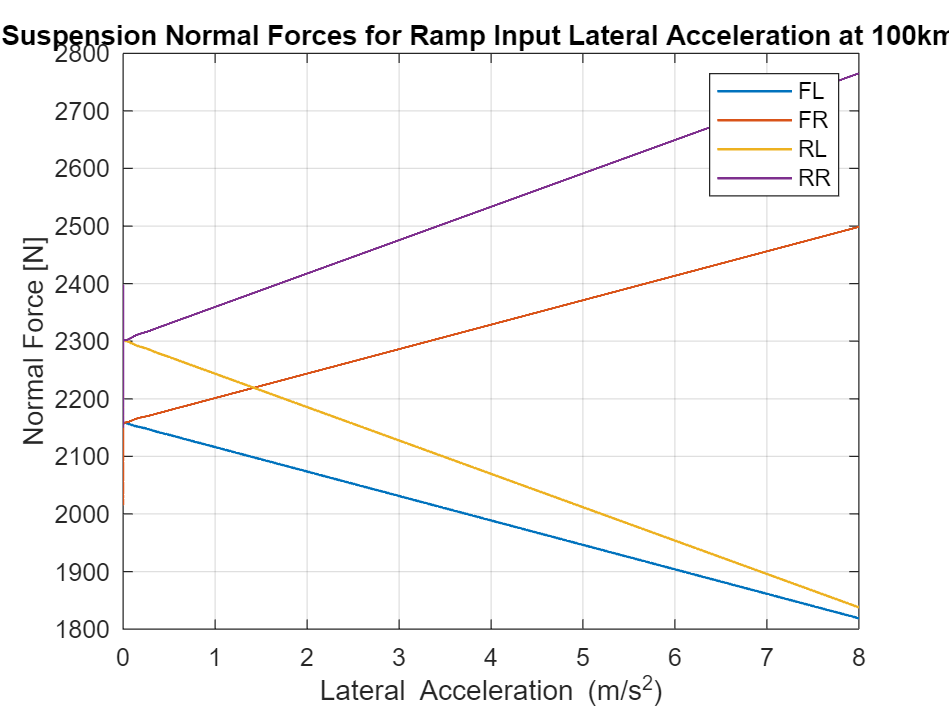

load("Load_Transfer.mat")

plot(Load_Transfer.latacc.data, Load_Transfer.Ftfl.data, "LineWidth",1)
hold on
plot(Load_Transfer.latacc.data, Load_Transfer.Ftfr.data, "LineWidth",1)
plot(Load_Transfer.latacc.data, Load_Transfer.Ftrl.data, "LineWidth",1)
plot(Load_Transfer.latacc.data, Load_Transfer.Ftrr.data, "LineWidth",1)
xlabel('Lateral Acceleration (m/s^2)')
ylabel('Normal Force [N]')
title('Suspension Normal Forces for Ramp Input Lateral Acceleration at 100km/h')
legend(['FL'; 'FR'; 'RL'; 'RR'])
hold off
grid on


deltaFz_FR = 2328.74 - 2150.2

deltaFz_FR = 178.5400

deltaFz_RR = 2533.48 - 2302.63

deltaFz_RR = 230.8500

Suspension Natural Frequencies - Heave and wheel hop frequency calculations vs model outputs.

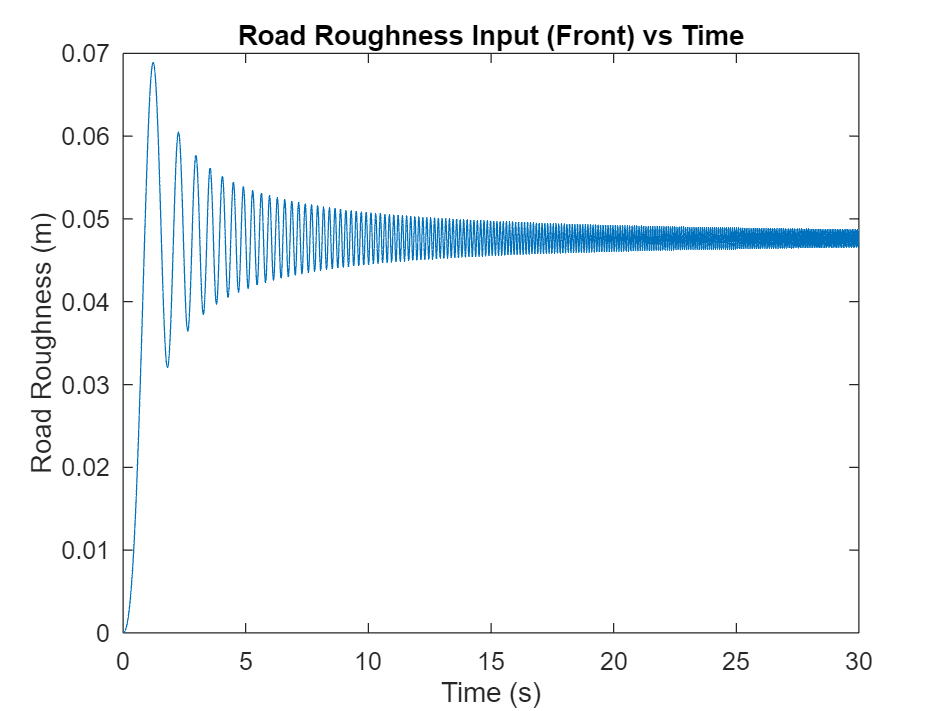

load("Freq_Sweep.mat")

plot(Freq_Sweep.z_road.time, Freq_Sweep.z_road.data)
title('Road Roughness Input (Front) vs Time')
xlabel('Time (s)')
ylabel('Road Roughness (m)')
xlim([0 30])

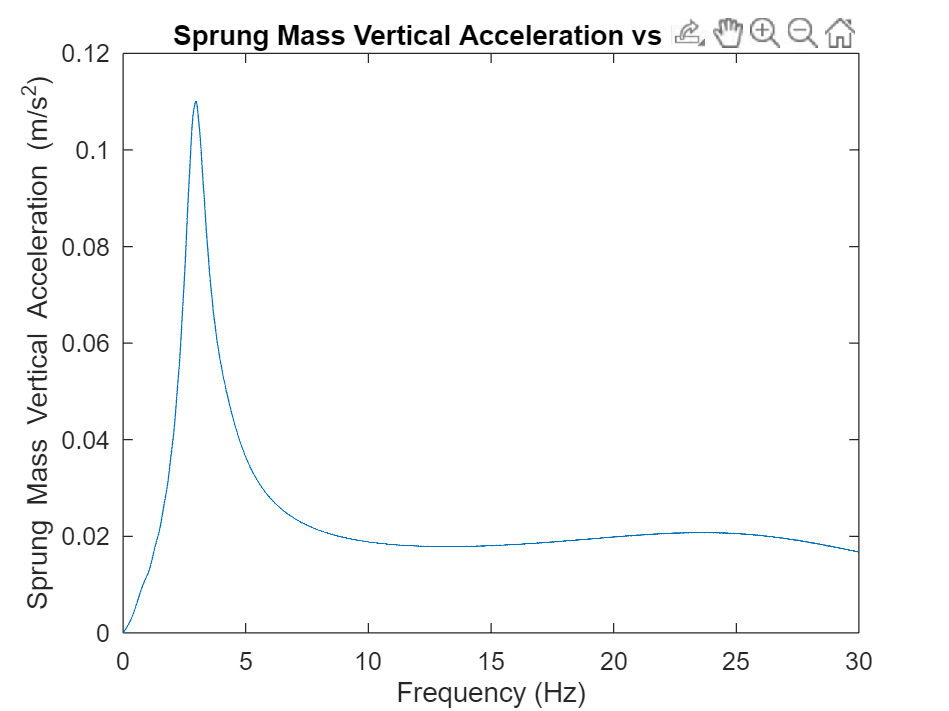


dt = 0.005;

[amps, phases, freqs] = fft_VD(Freq_Sweep.zsdotdot.data,dt);

plot(freqs,amps)
title('Sprung Mass Vertical Acceleration vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Sprung Mass Vertical Acceleration (m/s^2)')
xlim([0 30])


f_frontcorner = sqrt(ksf/(0.5*ms_front))/(2*pi)
f_rearcorner = sqrt(ksr/(0.5*ms_rear))/(2*pi)

Heave Frequency ~ 2.97 Hz

[ampfWH, phasefWH, freqfWH] = fft_VD(Freq_Sweep.zusfldotdot.data,dt);

f_wheelhopfront = 28.0973

f_wheelhoprear = 26.9021

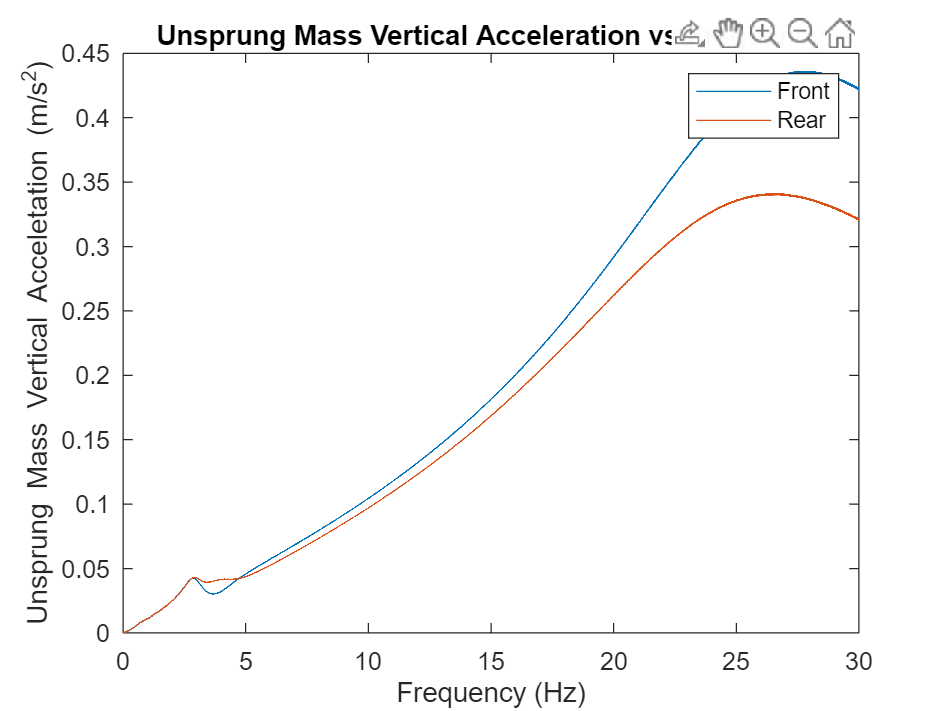

[amprWH, phaserWH, freqrWH] = fft_VD(Freq_Sweep.zusrldotdot.data,dt);

plot(freqfWH,ampfWH)
hold on
plot(freqrWH,amprWH)
title('Unsprung Mass Vertical Acceleration vs Frequency')
xlabel('Frequency (Hz)')
ylabel('Unsprung Mass Vertical Acceletation (m/s^2)')
legend('Front', 'Rear')
xlim([0 30])
hold off


f_wheelhopfront = (1/(2*pi))*sqrt((ktyre+ksf)/musf)
f_wheelhoprear = (1/(2*pi))*sqrt((ktyre+ksr)/musr)

Model output front wheel hop frequency = 27.72 Hz

Model output rear wheel hop frequency = 26.58 Hz